# **1.Tasks 1&2 (clean & tidy data)**

clc 
clear all
warning off
% read data from file
dal = readtable('DEhourlyload.csv');%29-DE
dap1 = readtable('Day-ahead_prices_2019_2020.csv');
dap1 = dap1(:,1:3);
dap2 = readtable('Day-ahead_prices_2021.csv');
dap2 = dap2(:,1:3);
dap = [dap1;dap2];
C= datetime(year(dap.Date),month(dap.Date),day(dap.Date),hour(dap.TimeOfDay),minute(dap.TimeOfDay),second(dap.TimeOfDay));
dap.Time_CET_CEST_ = C;
dap = removevars(dap,{'Date','TimeOfDay'});
dap = movevars(dap,'Germany_Luxembourg___MWh_','After','Time_CET_CEST_');
%find the position of the missing time
G = dap(3==month(dap.Time_CET_CEST_),:);
G11 = groupsummary(G,"Time_CET_CEST_",'day');
[m,n] = find(G11.GroupCount == min(G11.GroupCount));
G11.day_Time_CET_CEST_(m,:)%find the date of the missing data

ans = 3×1 categorical 数组
     2019-03-31 
     2020-03-29 
     2021-03-28 


G12 = groupsummary(G,"Time_CET_CEST_",'hourofday');
[m1,n1] = find(G12.GroupCount == min(G12.GroupCount));
G12.hourofday_Time_CET_CEST_(m1,:)% find the hour of the missing data

ans = categorical
     2 


%%find the position of the duplicate hour
G2 = dap([10==month(dap.Time_CET_CEST_) & 2==hour(dap.Time_CET_CEST_)],:);
G21 = groupsummary(G2,"Time_CET_CEST_",'hour');
[m2,n2] = find(G21.GroupCount == max(G21.GroupCount));
G21.hour_Time_CET_CEST_(m2,:)%find the date of the duplicate hour

ans = 3×1 categorical 数组
     2019-10-27 02:00:00 
     2020-10-25 02:00:00 
     2021-10-31 02:00:00 


% fill in the missing value in March with the average of the neighboring hours
%average the duplicate hour (2am) in October
t11 = dap(2019 == year(dap.Time_CET_CEST_) & 3 == month(dap.Time_CET_CEST_) & 31 == day(dap.Time_CET_CEST_) & [1 == hour(dap.Time_CET_CEST_)|3 == hour(dap.Time_CET_CEST_)] ,:);
g_arr(1,:) = mean(t11.Germany_Luxembourg___MWh_);
t12 = dap(2020 == year(dap.Time_CET_CEST_) & 3 == month(dap.Time_CET_CEST_) & 29 == day(dap.Time_CET_CEST_) & [1 == hour(dap.Time_CET_CEST_)|3 == hour(dap.Time_CET_CEST_)] ,:);
g_arr(2,:) = mean(t12.Germany_Luxembourg___MWh_);
t13 = dap(2021 == year(dap.Time_CET_CEST_) & 3 == month(dap.Time_CET_CEST_) & 28 == day(dap.Time_CET_CEST_) & [1 == hour(dap.Time_CET_CEST_)|3 == hour(dap.Time_CET_CEST_)] ,:);
g_arr(3,:) = mean(t13.Germany_Luxembourg___MWh_);
t21 = dap(2019 == year(dap.Time_CET_CEST_) & 10 == month(dap.Time_CET_CEST_) & 27 == day(dap.Time_CET_CEST_) & 2 == hour(dap.Time_CET_CEST_),:);
g_arr(4,:) = mean(t21.Germany_Luxembourg___MWh_);
t22 = dap(2020 == year(dap.Time_CET_CEST_) & 10 == month(dap.Time_CET_CEST_) & 25 == day(dap.Time_CET_CEST_) & 2 == hour(dap.Time_CET_CEST_),:);
g_arr(5,:) = mean(t22.Germany_Luxembourg___MWh_);
t23 = dap(2021 == year(dap.Time_CET_CEST_) & 10 == month(dap.Time_CET_CEST_) & 31 == day(dap.Time_CET_CEST_) & 2 == hour(dap.Time_CET_CEST_),:);
g_arr(6,:) = mean(t23.Germany_Luxembourg___MWh_);
d = {'2019-03-31 02:00:00' ,'2020-03-29 02:00:00','2021-03-28 02:00:00','2019-10-27 02:00:00','2020-10-25 02:00:00','2021-10-31 02:00:00'};
t = datetime(d,'InputFormat','yyyy-MM-dd HH:mm:ss')';
Time_CET_CEST_ = t;
Germany_Luxembourg___MWh_ = g_arr;
dap_add = table(Time_CET_CEST_,Germany_Luxembourg___MWh_);
dap_new = [dap;dap_add];
del_time1 = (4*31+28+3*30+26)*24 + 31*24-1 + 3;
dap_new(del_time1:del_time1+1,:) = [];
del_time2 = 365 *24 -2 + (4*31+29+3*30+24)*24 + 31*24-1 + 3 ;
dap_new(del_time2:del_time2+1,:)=[];
del_time3 = (365+366) *24 -4 + (4*31+28+3*30+30)*24 + 31*24-1 + 3 ;
dap_new(del_time3:del_time3+1,:)=[];
dap_new = sortrows(dap_new);

# **2.Tasks  3&4(plot)**

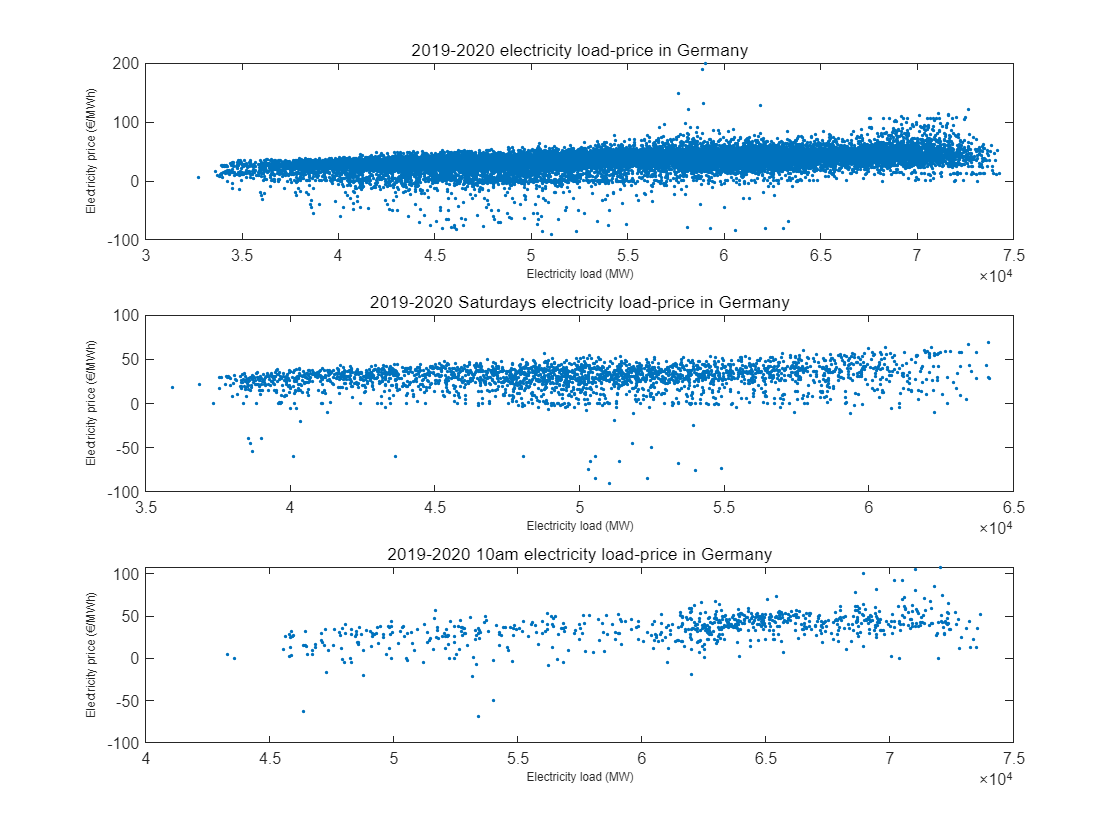

%%Task3-Prepare scatter plots of forecasted load vs. price for data from years 2019-2020:

%3.1 plot #1 for all data
figure('units','normalized','position',[0.1,0.1,0.6,0.8])
load_time =  table2array(dal(:,'Time_CET_CEST_'));
i = find(year(load_time) == 2019  | year(load_time) == 2020);
load_20192020_time = load_time(i);
load_20192020 = table2array(dal(i,'Day_aheadTotalLoadForecast_MW__BZN_DE_LU'));
price_20192020 = table2array(dap_new(i,'Germany_Luxembourg___MWh_'));
subplot(3,1,1)
plot(load_20192020,price_20192020,'.')
xlabel('Electricity load (MW)','FontSize',7)
ylabel('Electricity price (€/MWh)','FontSize',7)
title('2019-2020 electricity load-price in Germany')

%3.2 plot #2 for all hours on Saturdays
i1 = find(weekday(load_20192020_time) == 7);
load_Sat_time = load_20192020_time(i1);
load_Sat = load_20192020(i1);
price_Sat = price_20192020(i1);
subplot(3,1,2)
plot(load_Sat,price_Sat,'.')
xlabel('Electricity load (MW)','FontSize',7)
ylabel('Electricity price (€/MWh)','FontSize',7)
title('2019-2020 Saturdays electricity load-price in Germany')

%3.3 plot #3 for hour 10am on all days of the week.
i2 = find(hour(load_20192020_time) == 10);
load_10am_time = load_20192020_time(i2);
load_10am = load_20192020(i2);
price_10am = price_20192020(i2);
subplot(3,1,3)
plot(load_10am,price_10am,'.')
xlabel('Electricity load (MW)','FontSize',7)
ylabel('Electricity price (€/MWh)','FontSize',7)
title('2019-2020 10am electricity load-price in Germany')
hold off

%% Task4-Prepare weekly and daily seasonal plots for both the price and load data from years 2019-2020. 

% plot daily seasonal plots for load data from years 2019-2020.
figure('units','normalized','position',[0.1,0.1,0.8,1.6])
subplot(4,1,1)
load_day = reshape(load_20192020,24,[]);
plot(timeofday(load_20192020_time(1:24)),load_day')
xlabel('Time of day','FontSize',7)
ylabel('Electricity load (MW/h)','FontSize',7)
title('2019-2020 daily electricity load in Germany')

% plot daily seasonal plots for price data from years 2019-2020.
subplot(4,1,2)
price_day =  reshape(price_20192020,24,[]);
plot(timeofday(load_20192020_time(1:24)),price_day')
xlabel('Time of day','FontSize',7)
ylabel('Electricity price (€/MWh)','FontSize',7)
title('2019-2020 daily electricity price in Germany')

% plot weekly seasonal plots for load data from years 2019-2020.
subplot(4,1,3)
ext = round(7 - [size(load_20192020,1)/(24*7) - floor(size(load_20192020,1)/(24*7))]*7)

ext = 4

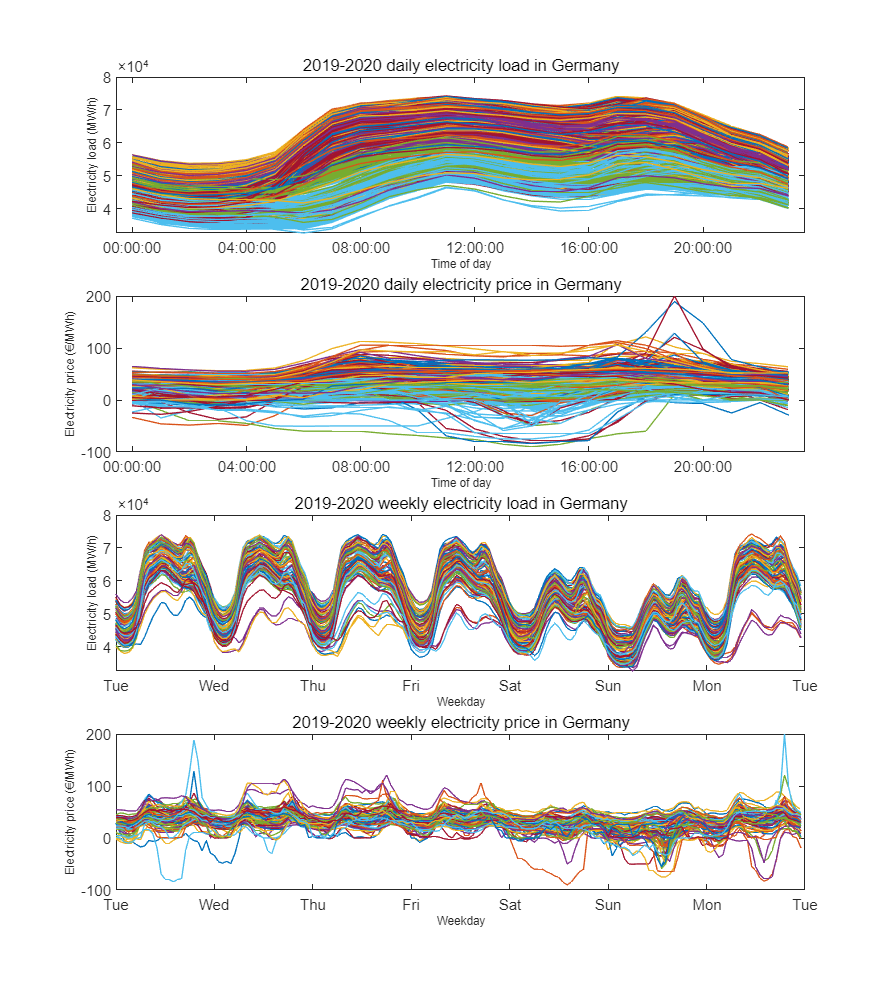

load_demand_ext = [load_20192020; NaN*ones(24*ext,1)];
load_week = reshape(load_demand_ext,24*7,[]);
plot(load_20192020_time(1:24*7),load_week')
datetick('x','ddd')
xlabel('Weekday','FontSize',7)
ylabel('Electricity load (MW/h)','FontSize',7)
title('2019-2020 weekly electricity load in Germany')

% plot weekly seasonal plots for price data from years 2019-2020.
subplot(4,1,4)
price_week_ext = [price_20192020; NaN*ones(24*ext,1)];
price_week =  reshape(price_week_ext,24*7,[]);
plot(load_20192020_time(1:24*7),price_week')
datetick('x','ddd')
xlabel('Weekday','FontSize',7)
ylabel('Electricity price (€/MWh)','FontSize',7)
title('2019-2020 weekly electricity price in Germany')
hold off

# **3.Tasks  5&6&9(for naive#1 &naive#2)**

%%Task5+9-Compute forecasts of the naive #1 for each hour separately and joinly for all hours in 2021.
price_time = table2array(dap_new(:,'Time_CET_CEST_'));
price = table2array(dap_new(:,'Germany_Luxembourg___MWh_'));
price_time = price_time(1:(731+298)*24);%not all year,till 2021.10.25
price = price(1:(731+298)*24);%not all year,till 2021.10.25
T = 731;
N = size(price,1);
pf168 = zeros(N/24,1);
pf7 = zeros(N,1);
for hour = 1:24
    p_h7 = price(hour:24:end);
    for j = T+1:length(p_h7)
        pf168(j) = p_h7(j-7);
    end
    pf7(hour:24:end)=pf168;
    mae = mean(abs(p_h7(T+1:end) - pf168(T+1:end)));
    rmse = (mean((p_h7(T+1:end) - pf168(T+1:end)).^2)).^0.5;
    disp (['MAE and RMSE of naive #1 model in ' num2str(hour-1) ':00 in 2021 are MAE: ' num2str(mae) ' , RMSE: ' num2str(rmse)])
    if hour == 24
        mae1 = mean(abs(price(T*24+1:end) - pf7(T*24+1:end)));
        rmse1 = (mean((price(T*24+1:end) - pf7(T*24+1:end)).^2)).^0.5;
        disp (['MAE and RMSE of naive #1 model for all hours in 2021 are MAE: ' num2str(mae1) ' , RMSE: ' num2str(rmse1)])
    end
end

MAE and RMSE of naive #1 model in 0:00 in 2021 are MAE: 18.5961 , RMSE: 30.1153
MAE and RMSE of naive #1 model in 1:00 in 2021 are MAE: 18.1584 , RMSE: 29.9706
MAE and RMSE of naive #1 model in 2:00 in 2021 are MAE: 17.8648 , RMSE: 29.7811
MAE and RMSE of naive #1 model in 3:00 in 2021 are MAE: 17.7557 , RMSE: 29.6393
MAE and RMSE of naive #1 model in 4:00 in 2021 are MAE: 17.8224 , RMSE: 29.4216
MAE and RMSE of naive #1 model in 5:00 in 2021 are MAE: 17.3461 , RMSE: 29.3363
MAE and RMSE of naive #1 model in 6:00 in 2021 are MAE: 18.3323 , RMSE: 30.7023
MAE and RMSE of naive #1 model in 7:00 in 2021 are MAE: 20.1269 , RMSE: 32.4672
MAE and RMSE of naive #1 model in 8:00 in 2021 are MAE: 22.208 , RMSE: 36.2549
MAE and RMSE of naive #1 model in 9:00 in 2021 are MAE: 22.5134 , RMSE: 36.0688
MAE and RMSE of naive #1 model in 10:00 in 2021 are MAE: 23.0324 , RMSE: 36.0279
MAE and RMSE of naive #1 model in 11:00 in 2021 are MAE: 23.3894 , RMSE: 36.054
MAE and RMSE of naive #1 model in 12:00 

MAE and RMSE of naive #1 model for all hours in 2021 are MAE: 20.7339 , RMSE: 33.201


%%Task6+9-Compute forecasts of the naive #2 for each hour separately and joinly for all hours in 2021.
dow = weekday(price_time)-1;
dow1 = dow(1:24:end);
pf1_7 = zeros(N/24,1);
PF1_7 = zeros(N,1);
for hour = 1:24
    p_1_7 = price(hour:24:end);
    for j = T+1:length(p_1_7)
        switch dow1(j)
            case{1,6,0}%1-Mon,6-Sat,0-Sun
                pf1_7(j) = p_1_7(j-7);%take price 168h ago
            otherwise %Tue,Wed,Thu,Fri
                pf1_7(j) = p_1_7(j-1);
        end
    end
    PF1_7(hour:24:end) = pf1_7;
    mae2 = mean(abs( p_1_7(T+1:end) - pf1_7(T+1:end)));
    rmse2 = (mean(( p_1_7(T+1:end) - pf1_7(T+1:end)).^2)).^0.5;
    disp (['MAE and RMSE of naive #2 model in ' num2str(hour-1) ':00 in 2021 are MAE: ' num2str(mae2) ' , RMSE: ' num2str(rmse2)])
    if hour == 24
        mae3 = mean(abs(price(T*24+1:end) - PF1_7(T*24+1:end)));
        rmse3 = (mean((price(T*24+1:end) - PF1_7(T*24+1:end)).^2)).^0.5;
        disp (['MAE and RMSE of naive #2 model for all hours in 2021 are MAE: ' num2str(mae3) ' , RMSE: ' num2str(rmse3)])
    end
end

MAE and RMSE of naive #2 model in 0:00 in 2021 are MAE: 15.6135 , RMSE: 26.437
MAE and RMSE of naive #2 model in 1:00 in 2021 are MAE: 15.2968 , RMSE: 25.9941
MAE and RMSE of naive #2 model in 2:00 in 2021 are MAE: 14.6882 , RMSE: 25.392
MAE and RMSE of naive #2 model in 3:00 in 2021 are MAE: 14.7945 , RMSE: 25.0379
MAE and RMSE of naive #2 model in 4:00 in 2021 are MAE: 15.1078 , RMSE: 25.2848
MAE and RMSE of naive #2 model in 5:00 in 2021 are MAE: 14.8298 , RMSE: 25.7293
MAE and RMSE of naive #2 model in 6:00 in 2021 are MAE: 15.3851 , RMSE: 26.7727
MAE and RMSE of naive #2 model in 7:00 in 2021 are MAE: 16.7502 , RMSE: 27.9711
MAE and RMSE of naive #2 model in 8:00 in 2021 are MAE: 18.1439 , RMSE: 29.4589
MAE and RMSE of naive #2 model in 9:00 in 2021 are MAE: 17.8789 , RMSE: 29.0466
MAE and RMSE of naive #2 model in 10:00 in 2021 are MAE: 18.8593 , RMSE: 30.2416
MAE and RMSE of naive #2 model in 11:00 in 2021 are MAE: 19.1502 , RMSE: 29.8764
MAE and RMSE of naive #2 model in 12:00 

MAE and RMSE of naive #2 model for all hours in 2021 are MAE: 16.8583 , RMSE: 27.5358


# **4.Tasks 7&8&9(for fixed window & rolling window)**

%%Task 7+9 fixed calibration window
started = 1; %first day of calibration window
endd = 731; %last day of calibration window
Ndays = 298;%provided number of days to be predicted
N = size(dal,1);
data_table = [dap_new(1:N,:) dal(:,2)];
res_ARX = arx1(data_table,Ndays,started,endd);
started = 1; %first day of calibration window
endd = 731; %last day of calibration window
Ndays = 298;%provided number of days to be predicted
N = size(dal,1);
data_table = [dap_new(1:N,:) dal(:,2)];
res_ARX = arx1(data_table,Ndays,started,endd);
%compute and display MAE 
for hour = 1:24
    res_p = res_ARX(hour:24:end,1);
    res_fp = res_ARX(hour:24:end,2);
    if hour == 1
        disp(['MAE and RMSE for days ' num2str(endd+1) ' to ' num2str(N/24) ' across all hours in a fixed calibration window'])
        disp(['(length of the fixed calibration window for point forecasts = ' num2str(endd) ' days)'])
    end
    mae4 = mean(abs(res_p-res_fp));
    rmse4 = (mean((res_p-res_fp).^2)).^0.5;
    disp(['MAE and RMSE of ARX model in ' num2str(hour-1) ':00 are MAE: ' num2str(mae4) ' , RMSE: ' num2str(rmse4)]) 
    if hour == 24
        mae5 = mean(abs(res_ARX(:,1)-res_ARX(:,2)));
        rmse5 = (mean((res_ARX(:,1)-res_ARX(:,2)).^2)).^0.5;
        disp(['MAE and RMSE of ARX model for all hours are MAE: ' num2str(mae5) ' , RMSE: ' num2str(rmse5)]) 
    end
end

MAE and RMSE for days 732 to 1029 across all hours in a fixed calibration window


(length of the fixed calibration window for point forecasts = 731 days)


MAE and RMSE of ARX model in 0:00 are MAE: 6.1247 , RMSE: 10.3759
MAE and RMSE of ARX model in 1:00 are MAE: 7.6022 , RMSE: 12.479
MAE and RMSE of ARX model in 2:00 are MAE: 9.0813 , RMSE: 14.4187
MAE and RMSE of ARX model in 3:00 are MAE: 9.5941 , RMSE: 15.2294
MAE and RMSE of ARX model in 4:00 are MAE: 8.8772 , RMSE: 14.4481
MAE and RMSE of ARX model in 5:00 are MAE: 8.1148 , RMSE: 13.5961
MAE and RMSE of ARX model in 6:00 are MAE: 12.3774 , RMSE: 20.5401
MAE and RMSE of ARX model in 7:00 are MAE: 16.4024 , RMSE: 26.7727
MAE and RMSE of ARX model in 8:00 are MAE: 15.3488 , RMSE: 25.6186
MAE and RMSE of ARX model in 9:00 are MAE: 14.4361 , RMSE: 23.5547
MAE and RMSE of ARX model in 10:00 are MAE: 14.6182 , RMSE: 22.9233
MAE and RMSE of ARX model in 11:00 are MAE: 14.5473 , RMSE: 22.4835
MAE and RMSE of ARX model in 12:00 are MAE: 14.9075 , RMSE: 23.5091
MAE and RMSE of ARX model in 13:00 are MAE: 15.636 , RMSE: 25.3099
MAE and RMSE of ARX model in 14:00 are MAE: 15.8859 , RMSE: 25.839

MAE and RMSE of ARX model for all hours are MAE: 14.3148 , RMSE: 23.2538


%%Task 8+9 rolling calibration window
started = 1; %first day of calibration window
endd = 731; %last day of calibration window
Ndays = 298;%provided number of days to be predicted
N = size(dal,1);
data_table = [dap_new(1:N,:) dal(:,2)];
res_ARX = arx1(data_table,Ndays,started,endd);
started = 1; %first day of calibration window
endd = 731; %last day of calibration window
Ndays = 298;%provided number of days to be predicted
N = size(dal,1);
data_table = [dap_new(1:N,:) dal(:,2)];
res_ARX = arx2(data_table,Ndays,started,endd);
for hour = 1:24%compute and display MAE 
    res_p = res_ARX(hour:24:end,1);
    res_fp = res_ARX(hour:24:end,2);
    if hour == 1
        disp(['MAE and RMSE for days ' num2str(endd+1) ' to ' num2str(N/24) ' across all hours in a rolling calibration window'])
        disp(['(length of the rolling calibration window for point forecasts = ' num2str(endd) ' days)'])
    end
    mae4 = mean(abs(res_p-res_fp));
    rmse4 = (mean((res_p-res_fp).^2)).^0.5;
    disp(['MAE and RMSE of ARX model in ' num2str(hour-1) ':00 are MAE: ' num2str(mae4) ' , RMSE: ' num2str(rmse4)]) 
    if hour == 24
        mae5 = mean(abs(res_ARX(:,1)-res_ARX(:,2)));
        rmse5 = (mean((res_ARX(:,1)-res_ARX(:,2)).^2)).^0.5;
        disp(['MAE and RMSE of ARX model for all hours are MAE: ' num2str(mae5) ' , RMSE: ' num2str(rmse5)]) 
    end
end

MAE and RMSE for days 732 to 1029 across all hours in a rolling calibration window


(length of the rolling calibration window for point forecasts = 731 days)


MAE and RMSE of ARX model in 0:00 are MAE: 6.0406 , RMSE: 10.5708
MAE and RMSE of ARX model in 1:00 are MAE: 6.7284 , RMSE: 11.6597
MAE and RMSE of ARX model in 2:00 are MAE: 7.2871 , RMSE: 12.391
MAE and RMSE of ARX model in 3:00 are MAE: 7.8663 , RMSE: 12.9679
MAE and RMSE of ARX model in 4:00 are MAE: 8.0727 , RMSE: 13.3837
MAE and RMSE of ARX model in 5:00 are MAE: 8.1518 , RMSE: 13.575
MAE and RMSE of ARX model in 6:00 are MAE: 10.431 , RMSE: 17.2235
MAE and RMSE of ARX model in 7:00 are MAE: 12.2782 , RMSE: 19.8635
MAE and RMSE of ARX model in 8:00 are MAE: 13.84 , RMSE: 22.1892
MAE and RMSE of ARX model in 9:00 are MAE: 14.1826 , RMSE: 22.774
MAE and RMSE of ARX model in 10:00 are MAE: 14.6555 , RMSE: 22.929
MAE and RMSE of ARX model in 11:00 are MAE: 14.7049 , RMSE: 22.7918
MAE and RMSE of ARX model in 12:00 are MAE: 15.2365 , RMSE: 23.9533
MAE and RMSE of ARX model in 13:00 are MAE: 15.987 , RMSE: 25.468
MAE and RMSE of ARX model in 14:00 are MAE: 16.2304 , RMSE: 25.9568
MAE a

MAE and RMSE of ARX model for all hours are MAE: 12.4192 , RMSE: 20.778


function [result] = arx1(data_table,Ndays,started,endd)%fixed window
%data:1price;2load;3min price of d-1;4final hour of d-1;567Saturday&Sunday&Monday dummy
%result:1price,2forecasted price
i = weekday(data_table.Time_CET_CEST_(1))-1;
N = size(data_table,1);
data12 = table2array(data_table(:,2:end));
data = [data12 zeros(N,5)];
for j = 1:24:N%1/25/49***
   switch mod(i,7)
        case 6
            data(j:j+23,5) = 1;%Saturday dummy in column 5
        case 0
            data(j:j+23,6) = 1;%Sunday dummy in column 6
        case 1
            data(j:j+23,7) = 1;%Monday dummy in column 7
    end
    i = i+1;
    data(j:j+23,3) = min(data(j:j+23,1));
    data(j:j+23,4) = data(j+23,1);
end
result = zeros(Ndays*24,2);
result(:,1)=data(endd*24+1:(endd+Ndays)*24,1);%real price in 2021.1.1-2021.10.25
for hour = 1:24
    data_h = data(hour:24:end,:);
    DATA = data_h(started:endd,:);
    price1 = DATA(:,1);
    price_min = DATA(:,3);
    price_final = DATA(:,4);
    dummies = DATA(:,5:7);
    loadr = DATA(:,2);
    y = price1(8:end);
    %define explanatory variables for calibration
    x = [ones(size(y)) price1(7:end-1) price1(1:end-7) loadr(8:end) price_min(7:end-1) price_final(7:end-1) dummies(8:end,1:3)];
    %define explanatory variables for the following days
    x_fut = [ones(Ndays,1) data_h(endd:end-1,1) data_h(endd-6:end-7,1) data_h(endd+1:end,2) data_h(endd:end-1,3) data_h(endd:end-1,4) data_h(endd+1:end,5:7)];
    beta = regress(y,x);%estimate the ARX model
    prog = x_fut * beta;%compute a hour forecast in  
    result(hour:24:end,2) = prog;
end
end


%started = 1; %first day of calibration window
% endd = 731; %last day of calibration window
% Ndays = 298;%provided number of days to be predicted

function [result] = arx2(data_table,Ndays,started,endd)%rolling window
%data:1price;2load;3min price of d-1;4final hour of d-1;567Saturday&Sunday&Monday dummy
%result:1price,2forecasted price
i = weekday(data_table.Time_CET_CEST_(1))-1;
N = size(data_table,1);
data12 = table2array(data_table(:,2:end));
data = [data12 zeros(N,5)];
for j = 1:24:N%1/25/49***
   switch mod(i,7)
        case 6
            data(j:j+23,5) = 1;%Saturday dummy in column 5
        case 0
            data(j:j+23,6) = 1;%Sunday dummy in column 6
        case 1
            data(j:j+23,7) = 1;%Monday dummy in column 7
    end
    i = i+1;
    data(j:j+23,3) = min(data(j:j+23,1));
    data(j:j+23,4) = data(j+23,1);
end
result = zeros(Ndays*24,2);
result(:,1)=data(endd*24+1:(endd+Ndays)*24,1);%real price in 2021.1.1-2021.10.25
for j = 1:Ndays
    for hour = 1:24
        data_h = data(hour:24:end,:);
        DATA = data_h(started+(j-1):endd+j,:);
        price1 = DATA(1:end-1,1);
        price_min = DATA(1:end-1,3);
        price_final = DATA(1:end-1,4);
        dummies = DATA(2:end,5:7);
        loadr = DATA(2:end,2);
        y = price1(8:end);
        %define explanatory variables for calibration
        x = [ones(size(y)) price1(7:end-1) price1(1:end-7) loadr(7:end-1) price_min(7:end-1) price_final(7:end-1) dummies(7:end-1,1:3)];
        %define explanatory variables for day d+1(future day)
        x_fut = [1 price1(end) price1(end-6) loadr(end) price_min(end) price_final(end) dummies(end,1:3)];
        beta = regress(y,x);%estimate the ARX model
        prog = x_fut * beta;%compute a step-ahead forecast in 298 days.
        result((j-1)*24+hour,2) = prog;
    end
end
end